# Linear Least Regression Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

Linear regression analysis is a fundamental statistical method used to model and understand the relationship between two variables. By fitting a linear equation to a set of data points, this technique enables us to quantify the association between input and output variables. In this document, we delve into the provided code snippet, which showcases the process of performing linear regression analysis using MATLAB. We'll explore the theoretical foundations of linear regression and dissect each step of the code to comprehend how it calculates regression parameters and visualizes the resulting insights. Through this explanation, we aim to demystify the concept of linear regression and its practical implementation.

The goal of linear regression is to find a linear equation of the form $y=a_1 \ldotp x+a_0$, where $a_1$ represents the slope of line, and $a_0$ represents the y-intercept. 

### Part1: Input data

clear, clc
% These vectors are sample. You can change them later!
y = [4.5, 6.8, 7.3, 9.1, 11, 12.5, 14.2, 16.8, 18.1, 20.5];
x = [2.1, 3.5, 4.2, 5, 6.3, 7.1, 8, 9.4, 10.1, 11.5];

### Part2: Calculation process

In this part, a system of linear equations for finding the coefficients should be created. Its general form is:

$\left\lbrack \begin{array}{cc}
n & \sum_i \;x_i \\
\sum_i \;x_i  & \sum_i x_i^2 \;
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
a_0 \\
a_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sum_i y_i \;\\
\sum_i x_i y_i \;
\end{array}\right\rbrack \;\;$, so we can change the form to: $\left\lbrack \begin{array}{c}
a_0 \\
a_1 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
n & \sum_i \;x_i \\
\sum_i \;x_i  & \sum_i x_i^2 \;
\end{array}\right\rbrack }^{-1} \times \left\lbrack \begin{array}{c}
\sum_i y_i \;\\
\sum_i x_i y_i \;
\end{array}\right\rbrack \;$

Coeff = [length(x), sum(x); sum(x), sum(x .* x)];
Ans = [sum(y); sum(x .* y)];

Final = Coeff \ Ans;  
disp(['a0';'a1']), disp('='), disp(Final)

a0
a1
=
    0.4791
    1.7263



### Part3: Visualization

Visualization is one of the fast methods to see how much the linearization is accurate. Note that visualization just shows the quality of accuracy not its value! 

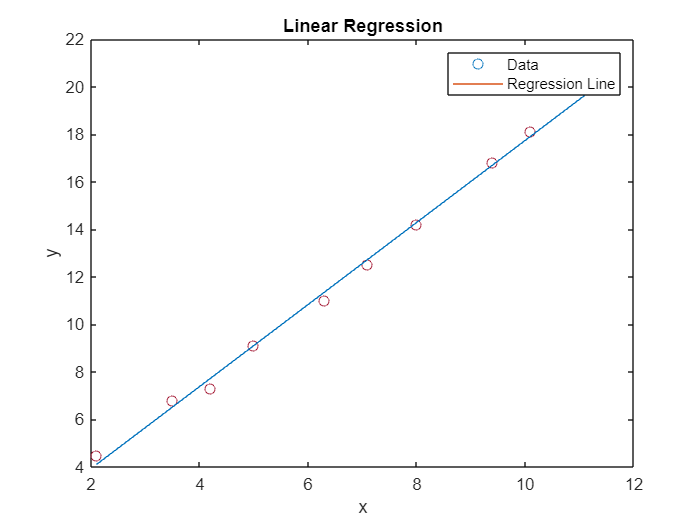

plot(x, y, 'o')  % Plot data points as circles
hold on

% Calculate the regression line
regression_line = Final(1) + Final(2) * x;
plot(x, regression_line)

xlabel('x')
ylabel('y')
title('Linear Regression')
legend('Data', 'Regression Line')

### Part4: Measurement of the linearization accuracy

Using Coefficient of determination ($r^2$), the accuracy of linearization can be measured easily. First, the Residual sum of squares should be calculated using the formula below:


$$S_r =\sum_{i=1}^n {\left(y_i -a_0 -a_1 x_i \right)}^2$$


Then, First, the mean deviation squares should be calculated by the following equation:


$$S_t =\sum_{i=1}^n {\left(y_i -\bar{y} \right)}^2$$



$$r^2 =\frac{\left(S_t -S_r \right)}{S_t }$$


y_new = ones(1,length(y));
for i= 1:length(y_new)
    y_new(i) = Final(1) + Final(2) * x(i);
end
Sr = sum((y - y_new).*(y - y_new));
St = sum((y- mean(y)).*(y- mean(y)));
r2 = (St - Sr)/St;
disp('The Coefficient of determination is: '), disp(r2)

The Coefficient of determination is: 
    0.9973

